## **An Introduction to ORB**

ORB (Oriented FAST and Rotated BRIEF) is an algorithm for fast feature point extraction and description,ORB is an improved algorism based on **oFAST** detector and rBRIEF descriptor.The algorithm was proposed by Ethan Rublee, Vincent Rabaud, Kurt Konolige and Gary R. Bradski in a 2011 paper entitled "ORB: An Efficient Alternative to SIFTor SURF".The ORB algorithm is divided into two parts, feature point extraction(Detector) and feature point description(Descriptor). The feature extraction is developed from the FAST (Features from Accelerated Segment Test) algorithm, and rBRIEF.So this introduction will be diveded in 4 parts.

- FAST detector

- oFAST detector

- BRIEF descriptor

- rBRIEF:an improved BRIEF descriptor based on oFAST (Only a introdution without implementation)

## **FAST detector**

Compared with Harris detector,the FAST detetor has significantly faster speed as the name suggests.This detector only take 4 steps to find the features.

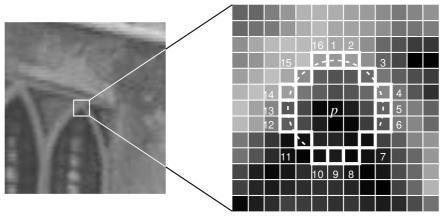

**Figure1**

- A pixel P is selected from the image, and in the following we will determine whether it is a feature point or not. We first assume its image intensity is Ip

- Set a suitable threshold t.

- Consider a discretized Bresenham circle with a radius equal to 3 with 16 pixels on the boundary of this circle.

- Now, if there are n consecutive pixel points on this circle, all of which have intensity values either larger than Ip+t or smaller than Ip-t, then it is a corner point. (as shown by the white dashed line in Figure 1). The value of n can be set to either 12 or 9, and experiments have shown that choosing 9 may give better results.In the code below,we set n to 12.

Let's compare it with the harris detector,it also takes 4 steps to find a feature point.

- Calculate the first order Gaussian partial derivatives Ix and Iy of the image in the x and y directions.

- Define the Harris matrix $G\;$for each pixel according Ix and Iy and calculate the two eigensvalue of the matrix.

- Calculate the $H$ for each pixel according to $H=\det \left(G\right)-{\textrm{tr}}^2 \left(G\right)$.

- Compare $H$ with threshold tau to determine whether it is a feature point or not.

As you can see,in order to determine a feature point,the Harris detector requires much more caculations than the FAST detector.

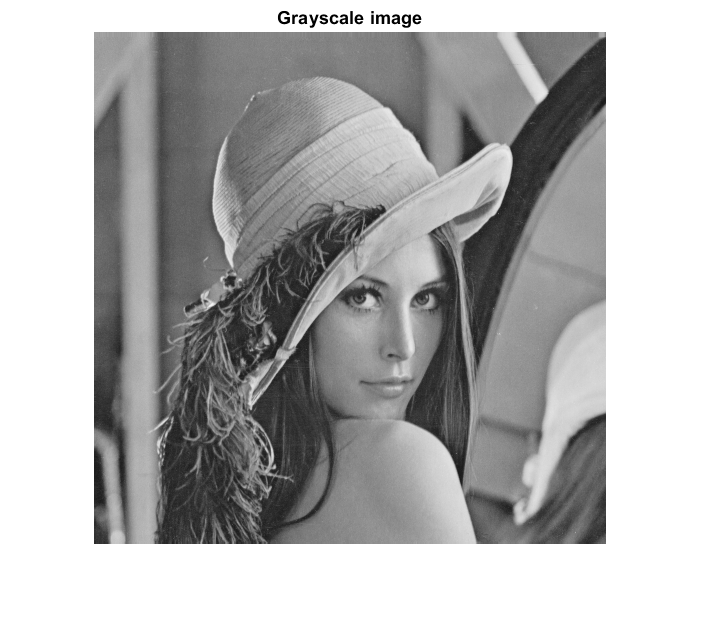

pic=imread('lena_std.tif');
pic=rgb2gray(pic);
figure;imshow(pic);title('Grayscale image');%Firstly we import the origiual picture and 

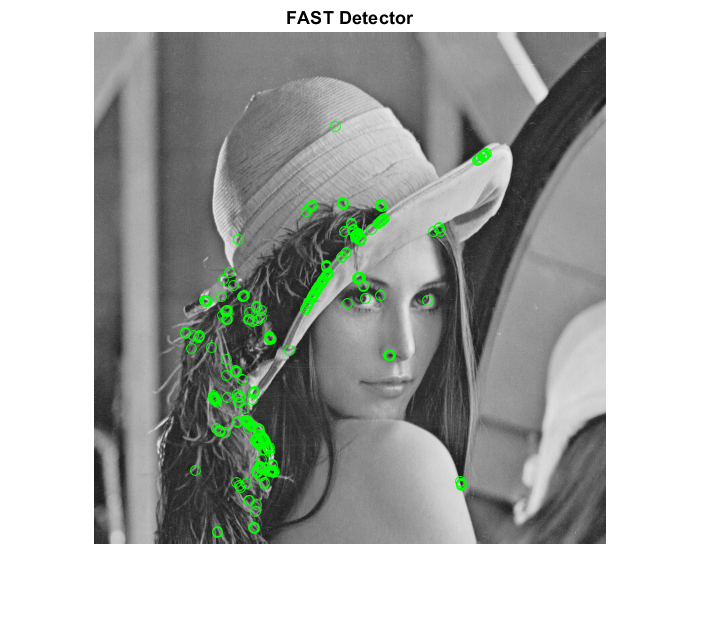

% change it into gray image.
threshold=50;%threshold
figure;imshow(pic);title('FAST Detector');hold on;
[Response,features]=Fastdetector(pic,threshold);

features=uint16(features);
total=length(features);

#### Non-Maximum Suppression

As you can see above there're too many feature points gathered in some very small place s,so we need to use non-Maximum Suppression.This method is also used in Harris detector.

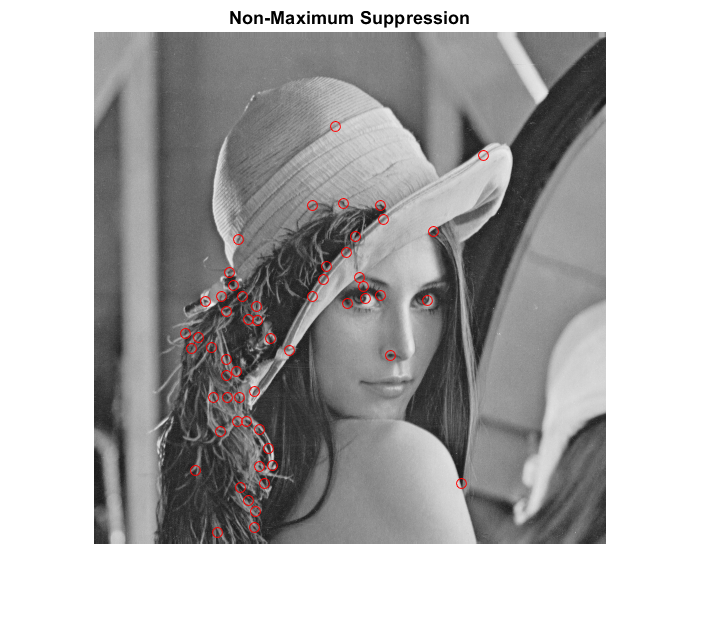

figure;imshow(pic);title('Non-Maximum Suppression');hold on;
window_n=15;
%A window is a n*n square used to suppress the Non-Maximum Value,
% you can adjust this parameter,it has to be an odd number.
features=Nonmaximum(features,Response,window_n,total);

As we can see 

## oFAST detector

After extracting the feature points using FAST, define a feature point orientation to achieve rotation of the feature points without distortion.We can easily konw that the feature points detected by FAST have no rotational invariance.The ORB algorithm proposes to use the method of intensity centroid to determine the direction of a FAST feature point. It takes 3 step to find the orientation of a feature point.

- Firstly select a small patch centered on the feature point

- Caculate the intensity centroid.

- Caculate the orientation of feature point according to the intensity centroid

To caculate the intensity centroid and orientation,we can follow this formular:


$$m_{\textrm{pq}} =\sum_{x,y} x^p y^q I\left(x,y\right)$$



$$C=\left(\frac{m_{10} }{m_{00} },\frac{m_{01} }{m_{00} }\right)$$



$$\theta =\textrm{actan}\left(\frac{m_{01} }{m_{10} }\right)$$


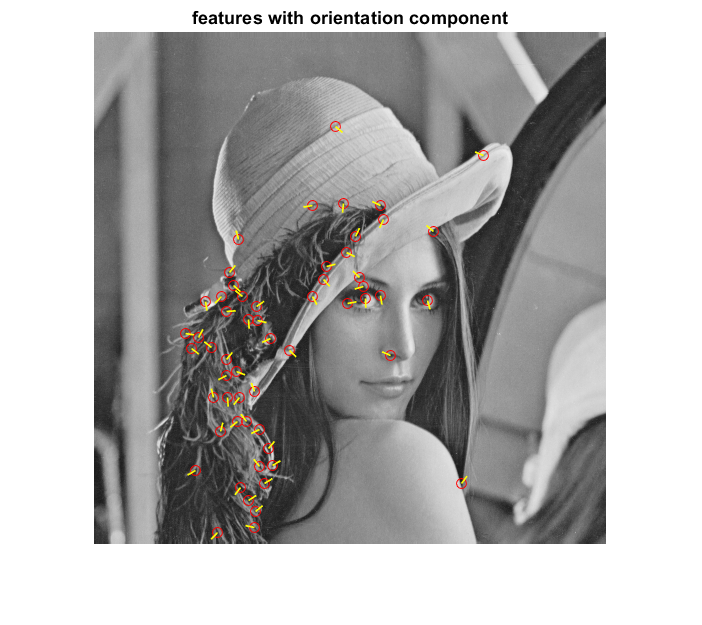

Fastfeatures=resort(features,total);
Patch_size=5;%define the size of patch
figure;imshow(pic);title('features with orientation component');hold on;
Feature_orientation=Orientation(pic,Fastfeatures,Patch_size);

The oFAST is to set the stage for rBRIEF,so that BRIEF descriptor can obtain some** rotation invariance**.We will deal with it later.

As for the scale invariance,the orb algorithm uses a multiscale image pyramid.An image pyramid(as you can see in Figure2) is a multi-scale representation of a single image, consisting of a series of different resolution versions of the original image. Each level of the pyramid consists of a downsampled version of the image from the previous level. Downsampling means that the resolution of the image has been reduced, for example by downsampling the image to a 1/2 scale. So what started as a 4x4 square area now becomes a 2x2 square. The image is downsampled to contain fewer pixels and is reduced in size by 1/2.

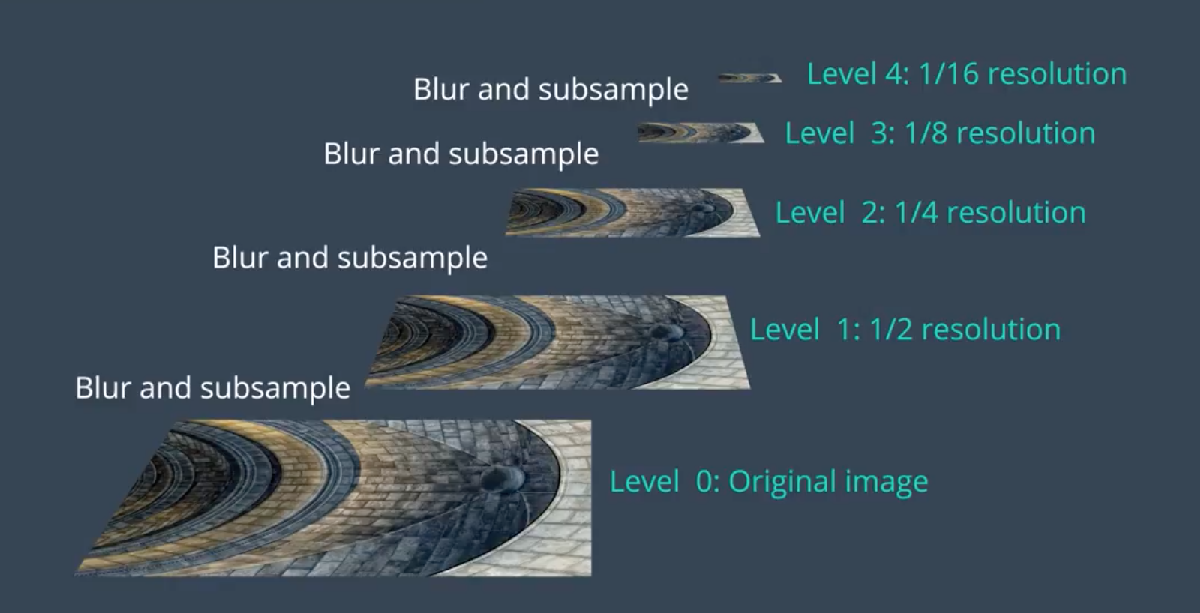

**Figure2**

This is an example of a image pyramid with 5 levels, at each level the image is downsampled by 1/2. Once ORB has created the image pyramid, it uses the FAST algorithm to quickly find key points from the different sizes of images at each level. Because each level of the pyramid consists of a smaller version of the original image, any objects in the original image will also be reduced in size at each level of the pyramid.

By determining the keypoints at each level ORB is able to efficiently find the keypoints of objects of different sizes, in which case ORB achieves partial scale invariance.

## BRIEF descriptor

Firstly,we need to konw about BRIEF descritor.BRIEF features, known as Binary Robust Independent Elementary Features, are a fast way to compute image feature descriptors, also reducing the time required for feature matching.

The algorithm calculates the following steps.

-  First calculate the feature points of an image,we use FAST detector mentioned above to detect them.

- Gaussian filter the image,choose 9 * 9 matrix, mainly to remove random noise.

- Take a patch of SxS, centred on the feature point. Pick a random pair (two) of points within the window, compare the size of the two pixels, and make the binary assignment.The S is set to 48 in the following code.

There are different ways to choose a strategy for random pixel pairs within the patch ,here I recommend to use Gaussian disribution: Both x and y pixels in the random pair are drawn from a Gaussian distribution or spread of ${0\ldotp 04S}^2$ around keypoint.

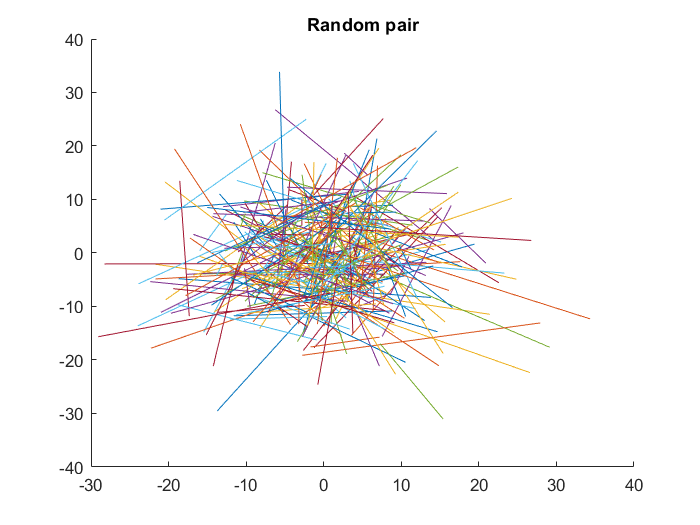

H=fspecial('gaussian',[9 9],2);
smoothpic=imfilter(pic,H);%Gaussian smoothing of the original picture
N=256;%number of random pair
Ps=48;%Patch size
s = normrnd(0,Ps/5,256,4);%generate 256 pixel pair in the patch
for i=1:total
     if (512-features(1,i)<Ps)||(512-features(2,i)<Ps)
        features(1,i)=0;
        features(2,i)=0;
     end %remove all the feature points which are to close to the border.
end
Fastfeatures=resort(features,total);
figure;title('Random pair');hold on;  %show distribution of random pair                           
for i=1:256
   plot(s(i,1:2),s(i,3:4));    
   hold on;
end

[Descriptor_BRIEF]=Desciptor(smoothpic,s,Fastfeatures,N);
%This matrix contain the 256bit decription data for each feature point

The BRIEF's strengths lie in its speed, and its weaknesses are obvious

- No rotational invariance 

- Sensitive to noise

- No scale invariance

By using a multiscale image pyramid,ORB obtains certain scale invariance,and we use Gaussian smoothing to reduce the nosie disturbance.As for rotational invariance,we need to improve BRIEF based on oFAST detector.

Recall that the BRIEF descriptor is calculated by selecting N pairs of points in a certain pattern around the current feature point P. The result of combining these N pairs is the final descriptor. When we select the pairs of points, the coordinate system is established with the current key point as the origin, the horizontal direction as the X-axis and the vertical direction as the Y-axis. When the image is rotated, the coordinate system remains the same, but the same point pattern selects different random pairs, and the calculated descriptors are not the same. We therefore need to recreate the coordinate system so that the new coordinate system can follow the rotation of the image. In this way we will have consistency in the points we take out with the same point pattern.

## **rBRIEF:an improved BRIEF descriptor based on oFAST**

We know that the Intensity Centroid of a patch is fixed and rotates with the rotation of the patch. When we konw the orientation componet of a feature point depending on oFAST detector,we can rebuild a new coordinate system so that the random pairs we take out with the same point pattern are the same for different rotation angles. This solves the problem of rotational invariance.The following code show the feature points orientation of a rotated picture.

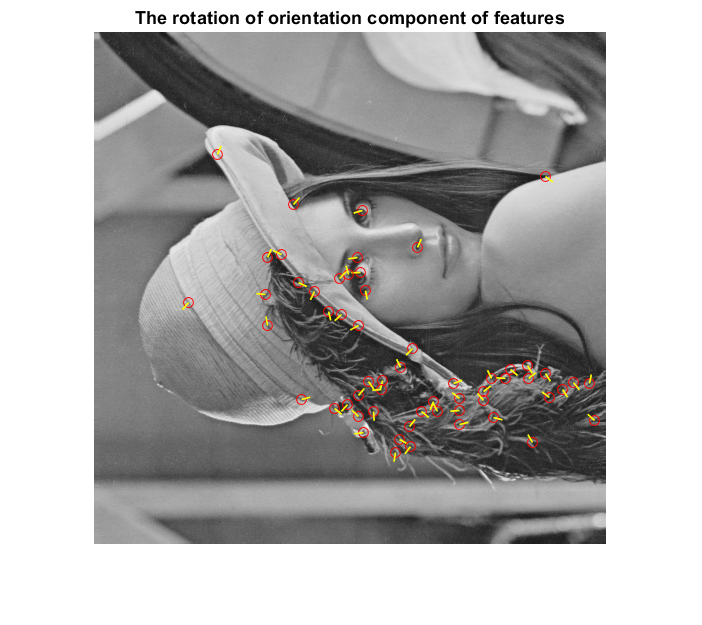

pic2=imread('lena_rotated.tif');%Treat the rotated picture
pic2=rgb2gray(pic2);
figure;set(figure,'visible','off');
[Response2,features2]=Fastdetector(pic2,threshold);
features2=uint16(features2);
total2=length(features2);
figure;set(figure,'visible','off');
features2=Nonmaximum(features2,Response2,window_n,total2);
Fastfeatures2=resort(features2,total2);
figure;imshow(pic2);title('The rotation of orientation component of features');hold on;
Feature_orientation2=Orientation(pic2,Fastfeatures2,Patch_size);

As you can see the orientation component rotates the same angle with the picture,in this case we konw that rBRIEF can be easily implemented.